# Enhancing Images

You've seen a number of techniques for systematically altering the image histograms to improve contrast. The image enhancement techniques in this reading are less focused on specific changes to an image's histogram. Instead, these more complex operations focus on making your images more clear for human observers. 

These techniques are not intended to directly improve image segmentation. Image processing is often the first step in a larger *computer vision* project, and part of computer vision is replicating and automating the tasks of human vision. In this context, increasing the visual clarity of an image may be an important pre-processing step.

Note: The techniques in this reading are more complex than those previously shown. The details of the algorithms involved are beyond the scope of this course.

## Haze Reduction

Atmospheric fog and haze can obscure the details in an image. This has implications for diverse applications from wildlife research to automated driving. The `imreducehaze` function reduces the effects of fog, smoke, and haze.

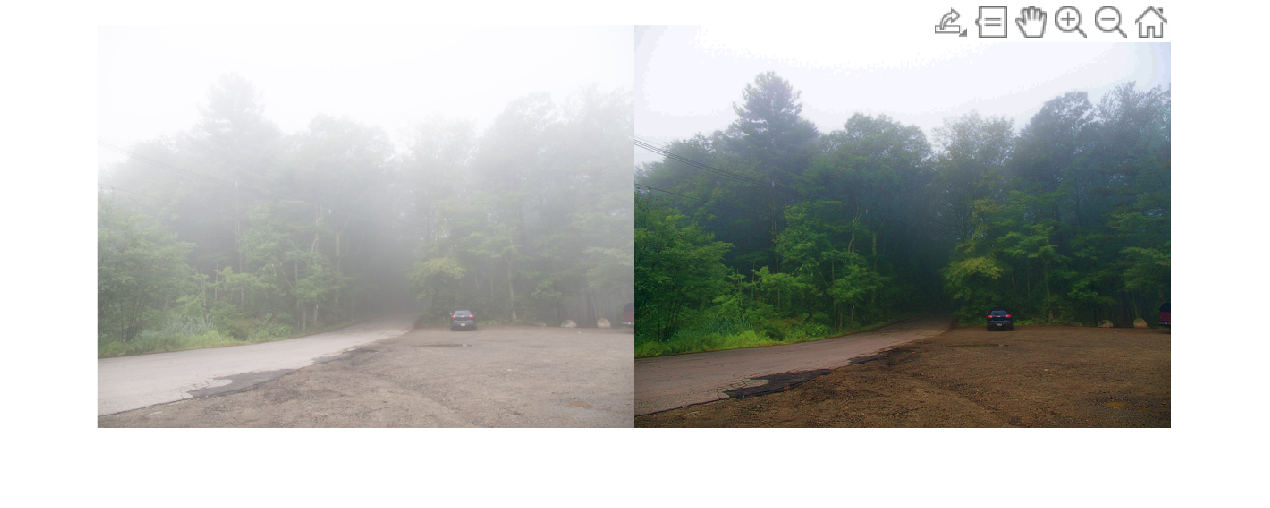

foggy = imread("foggyroad.jpg");
defogged = imreducehaze(foggy);
montage({foggy, defogged})

Snow and frost on objects in an image can have similar effects to atmospheric contaminants. The `imreducehaze` function can also improve the visibility in these cases.

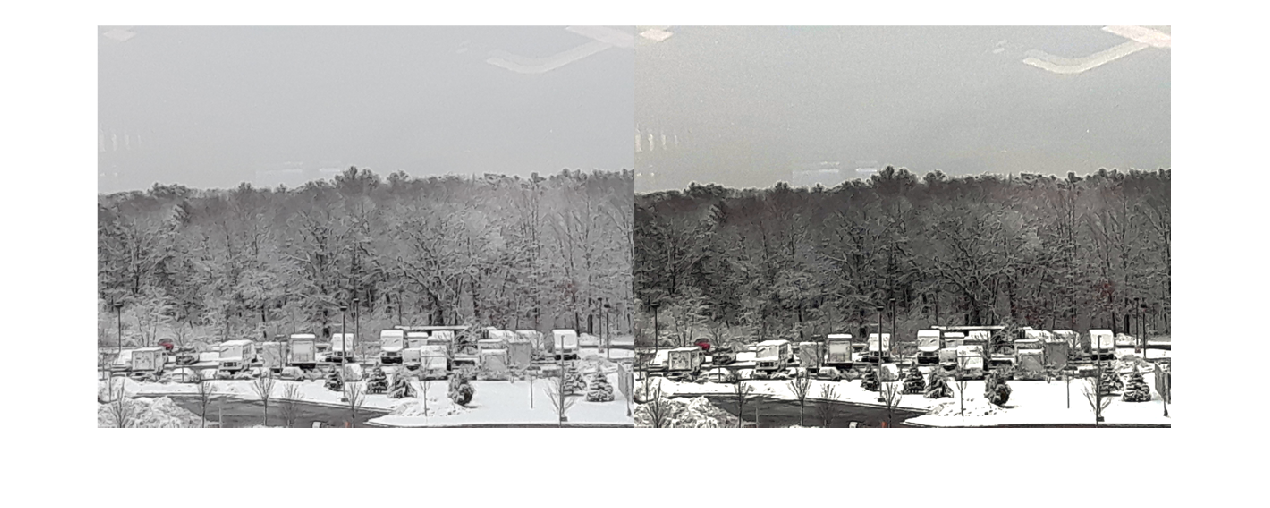

snowy = imread("mountain1.jpg");
cleared1 = imreducehaze(snowy);
montage({snowy, cleared1})

## Brightening Dark Images

Underexposed images use only part of the available brightness range. The `imadjust` function can increase the clarity of these images.  

But some dark images, such as the Boston waterfront image, are not underexposed - they use the full available brightness range, just not in a way that makes the objects in the image visible. Consider this image of Boston at night:

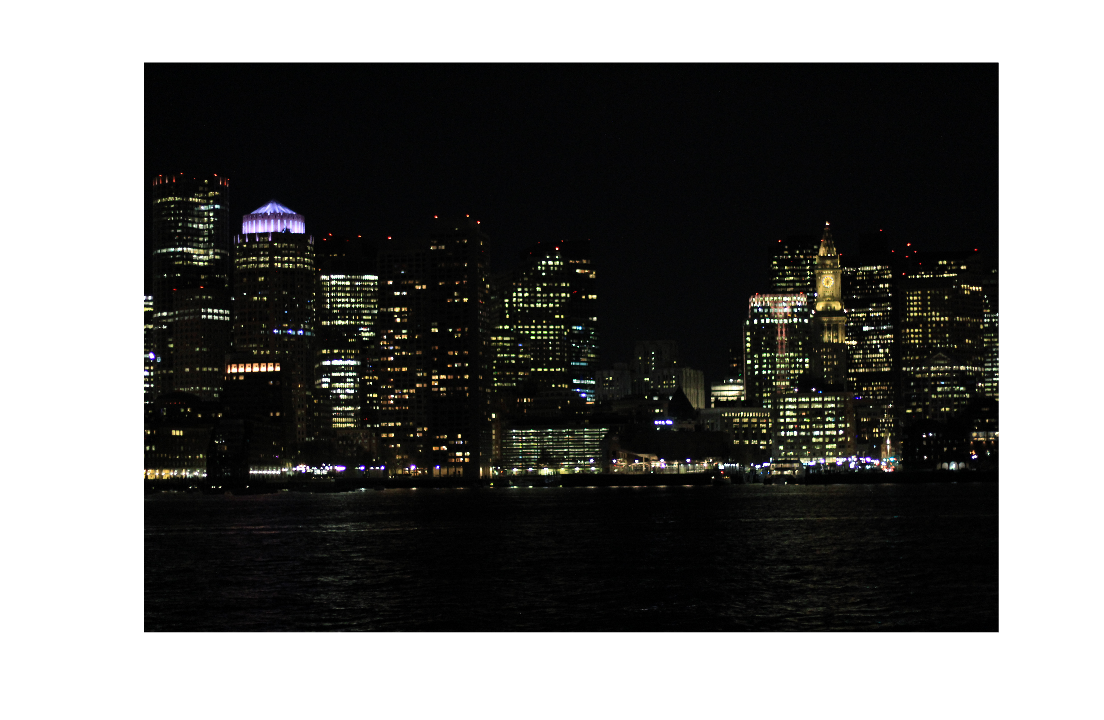

darkCity = imread("boston night.jpg");
imshow(darkCity)

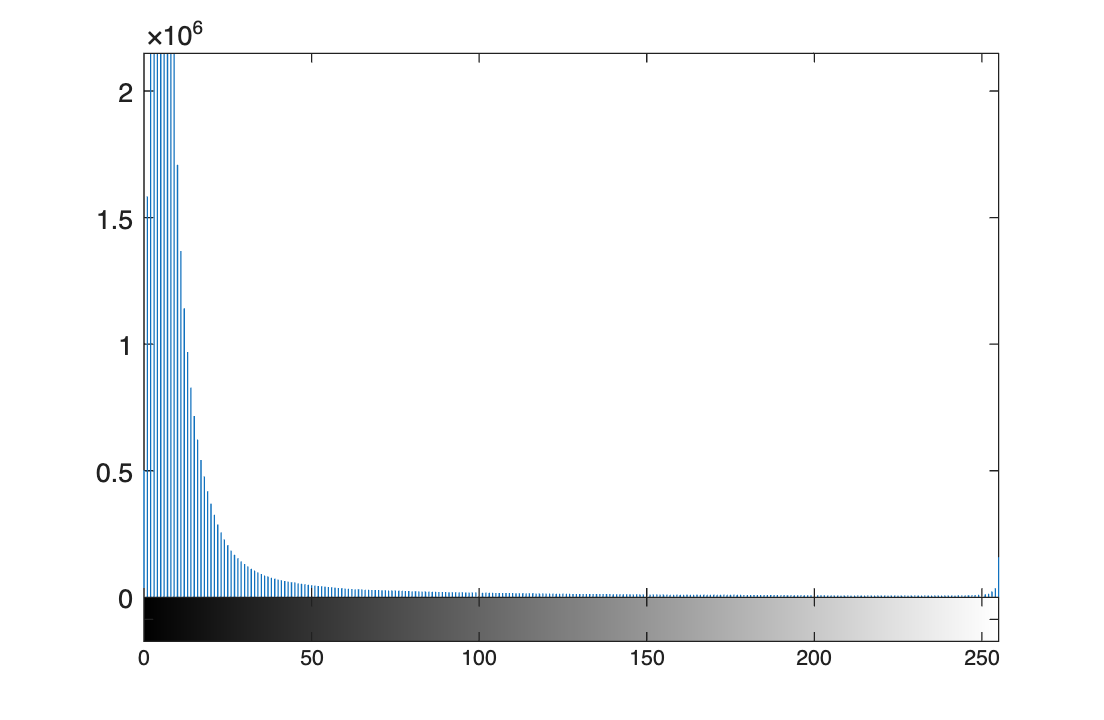

imhist(darkCity)

You can see that, due to the bright lights in the image, the image histogram does span the full, available range for uint8 images. However, the majority of the image is in darkness.

For this reason, operations such as imadjust are not very effective:

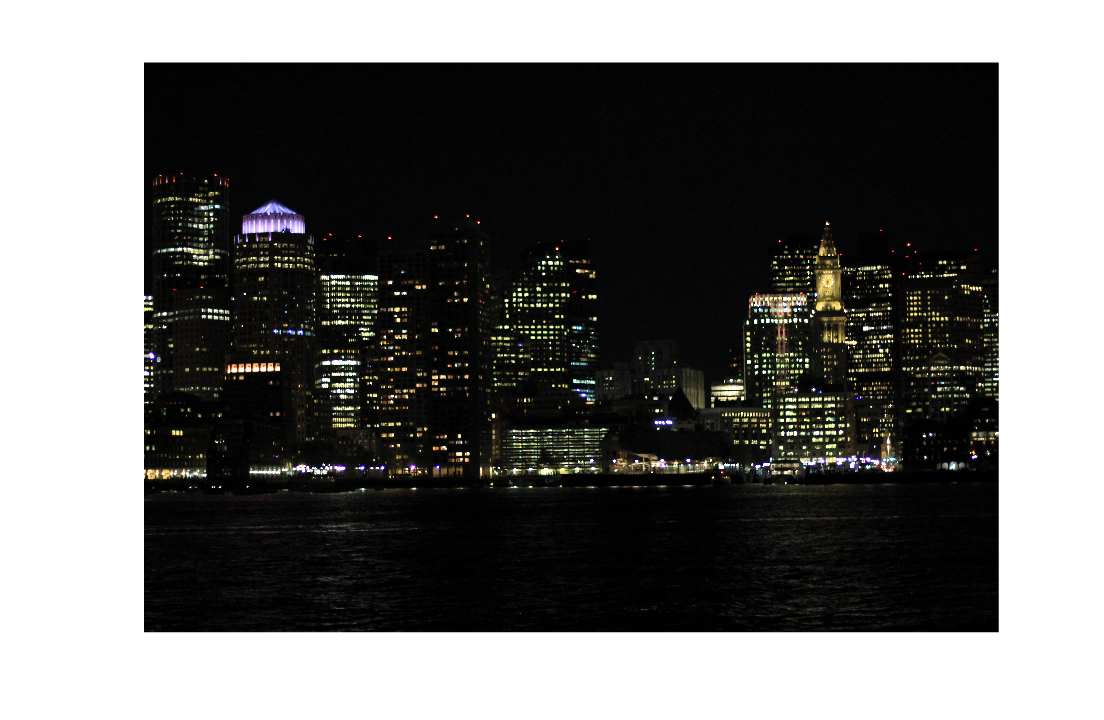

darkCityAdj = rgb2hsv(darkCity);
darkCityAdj(:,:,3) = imadjust(darkCityAdj(:,:,3));
darkCityAdj = im2uint8(hsv2rgb(darkCityAdj));
imshow(darkCityAdj)

For images like these, the `imlocalbrighten` function can increase the apparent lighting to reveal more of the subject. The function takes an optional parameter, `amount`, that determines how much the brightness is increased. This variable takes values between 0 and 1, with 1 being the default.

Notice how the darker parts of the image, such as the outlines of the buildings and the water, are far more visible.

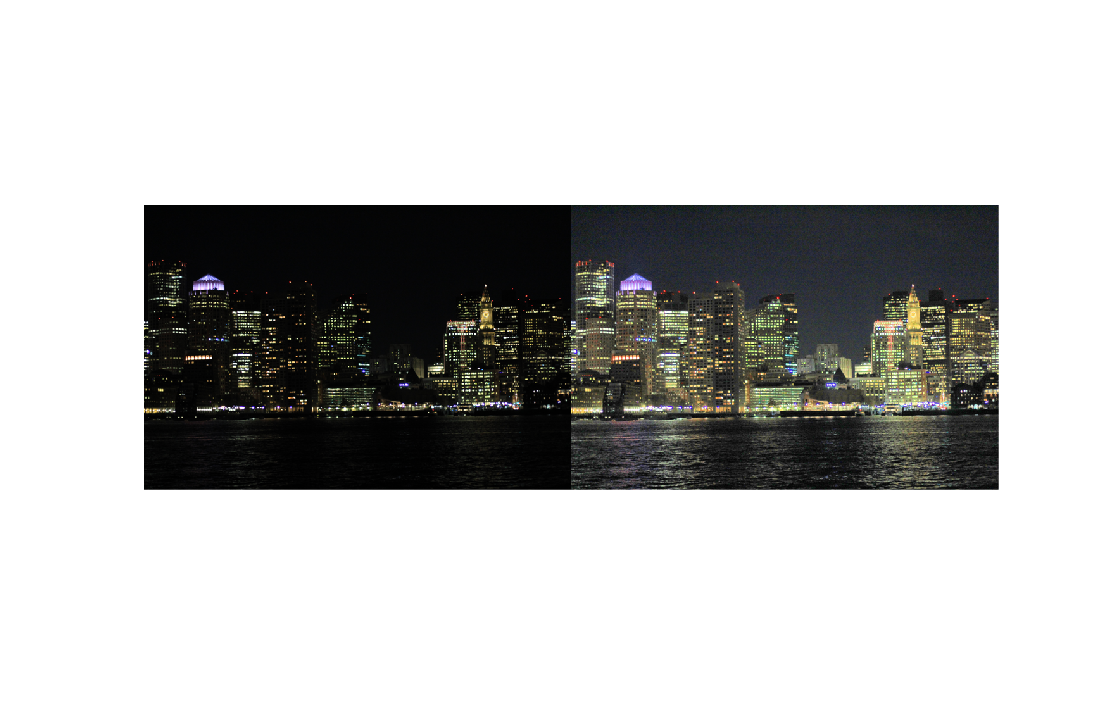

darkCity = imread("boston night.jpg");
amount = 0.9;
brightCity = imlocalbrighten(darkCity, amount);
montage({darkCity, brightCity})

The `imreducehaze` and `imlocalbrighten` functions are not meant to replace the contrast adjustment technique presented earlier.  They are computationally intensive and can add significant noise to an image. However, these functions provide an important supplement for cases when human visibility is important and the image histograms aren't especially well-suited to other methods of contrast adjustment.

*Copyright 2024 The MathWorks, Inc.*